# Lines and points

Using homogeneous coordinates, find the lines:

- through two points

- parallel to another line

- orthogonal to another line

## Select n points

At least 2

cd ~/Documents/Polimi/IACV/
I = imread('checkerboard.png');

figure(1), imshow(I.*255); hold on;
[x, y] = getpts();

Show the first two over the image

plot(x(1:2), y(1:2), 'r+', MarkerSize=10, LineWidth=2);

## Lines

### Line through two points

Cross product

a = [x(1); y(1); 1];
b = [x(2); y(2); 1];

l_through = cross(a,b)

l_through = 	1.0e+04 *

    0.0070
    0.0092
   -2.2266


### Parallel line through center

Find the direction by intersecting the line with the line at infinity. The parallel line passes through the center and the point at infinity found

shape = size(I);
s = shape(1);
center_image = [ s/2; s/2; 1];

infty = [0; 0; 1];
direction_l = cross(infty, l_through);

l_par = cross(center_image, direction_l);

### Line perpendicular to the previous passing through a

Line through a and the point at infinity in the direction orthogonal to the line

direction_orth = [ direction_l(2); -direction_l(1); 0];
l_orth = cross(a, direction_orth)

l_orth = 	1.0e+03 *

   -0.0920
    0.0700
   -6.6280


### Draw

Requires to go back to the cartesian representation

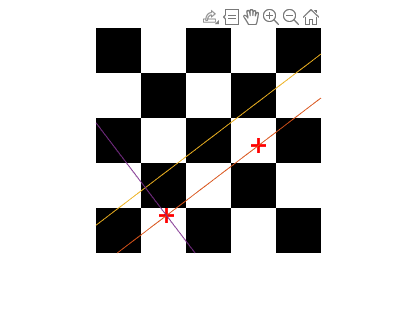

x_coord = linspace(0, 500);

l1 = homogeneous_to_cartesian(l_through);
l2 = homogeneous_to_cartesian(l_par);
l3 = homogeneous_to_cartesian(l_orth);

y1 = l1(1)*x_coord + l1(2);
y2 = l2(1)*x_coord + l2(2);
y3 = l3(1)*x_coord + l3(2);

plot(x_coord, y1);
plot(x_coord, y2);
plot(x_coord, y3);
hold off;

function cart = homogeneous_to_cartesian(h)
    cart = [-h(1)/h(2); -h(3)/h(2)];
end